Denoising Salt & Pepper con filtro Mediano

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);

% Aggiungo una sottocartella "output"
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');

Rumore e Immagine

nome_rumore = 'salt_pepper';
folderPath = fullfile(folderPath, nome_rumore);

nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);

Lettura Percorso

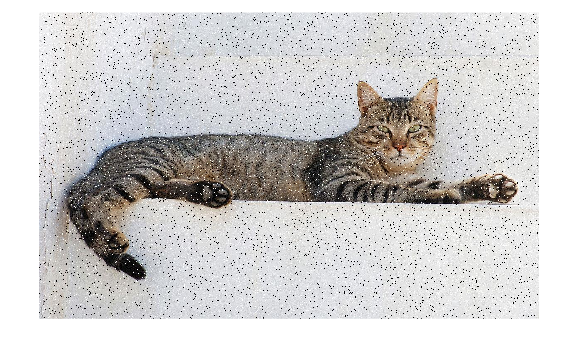

img_noisy = imread(folderPath);
imshow(img_noisy)

Check se l'immagine è effettivamente a colori con applicazione di un filtro mediano 3x3

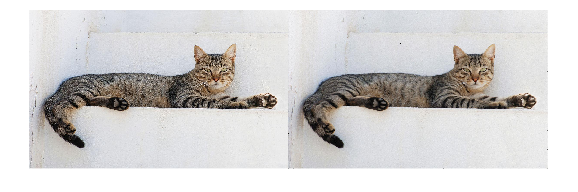

if size(img_noisy, 3) == 3
    img_denoised = img_noisy;
    for c = 1:3
        img_denoised(:,:,c) = medfilt2(img_noisy(:,:,c), [3 3]); % Finestra 3x3
    end
else
    img_denoised = medfilt2(img_noisy, [3 3]);
end

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);

% Aggiungo una sottocartella "output"
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);
i2 = imread(folderPath);
imshow(i2)
imshowpair(i2, img_denoised, 'montage');

img_denoised è la nuova immagine con rumore ridotto